# 问题描述：肿瘤分类问题

假设您要根据细胞大小、肿块厚度、有丝分裂等特征的均匀性将肿瘤分为良性或恶性。 您有 699 个样本，相关数据有 9 项，并且这些案例已正确分类为良性或恶性。 该数据集由 699 个九元素输入向量（X1到X9）和二元素目标（Y1和Y2）向量组成。 每个目标向量中有两个元素， 因为有两个类别（良性或恶性）与每个输入向量相关联。 参考 [https://ww2.mathworks.cn/help/deeplearning/gs/classify-patterns-with-a-neural-network.html](https://ww2.mathworks.cn/help/deeplearning/gs/classify-patterns-with-a-neural-network.html)

clear

## 创建网络。

用于函数拟合（或回归）问题的默认网络

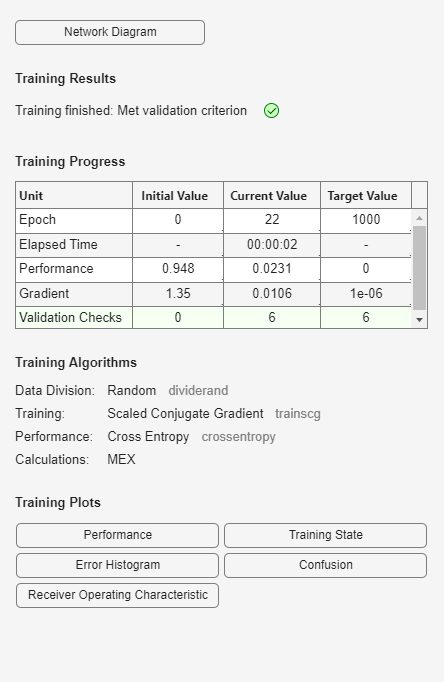

[inputs,targets] = cancer_dataset;

% patternnet 是一个前馈网络，其默认 tan-sigmoid 传递函数在隐藏层，softmax 传递函数在输出层。
% 首先，您（人为地选择）将十个神经元分配给一个隐藏层。
% 网络有两个输出神经元，因为有两个目标值（类别）与每个输入向量关联。每个输出神经元表示一个类别。
% 将相应类别的输入向量应用于网络时，对应的神经元应生成 1，其他神经元应输出 0。
% 要创建网络，请输入以下命令：

hiddenLayerSize = 10;
net = patternnet(hiddenLayerSize);
% 注意：模式识别问题的网络架构选择所遵循的规范与函数拟合问题类似。
% 神经元越多，需要的计算也越多；当数量设置得太高时，可能会出现数据过拟合倾向，
% 但这使网络能够求解更复杂的问题。层越多，需要的计算也越多，
% 但使用更多的层可以使网络更高效地求解复杂问题。
% 要使用多个隐藏层，请在 patternnet 命令中输入隐藏层大小作为数组的元素。

% 设置数据划分。

net.divideParam.trainRatio = 70/100;
net.divideParam.valRatio   = 15/100;
net.divideParam.testRatio  = 15/100;

% 基于以上设置，输入向量和目标向量都将被随机划分为三组，
% 其中 70% 用于训练，15% 用于验证，15% 用于测试。
% （有关数据划分流程的更多讨论，请参阅划分数据。）
% 训练网络。模式识别网络使用默认的量化共轭梯度 (trainscg) 算法进行训练。
% 要训练网络，请输入以下命令：

[net,tr] = train(net,inputs,targets);

% 在训练过程中，与函数拟合时一样，训练窗口将打开。
% 此窗口显示训练进度。要随时中断训练，请点击 Stop Training。

% 如果验证误差在六次迭代中持续增加，则训练将在第 24 次迭代时停止。
% 测试网络。您可以使用经过训练的网络来计算网络输出。以下代码将计算网络输出、误差和整体性能。

outputs = net(inputs);
errors = gsubtract(targets,outputs);
performance = perform(net,targets,outputs)  % performance =    0.0307

performance = 0.0354


% 通过使用训练记录中的测试索引，还可以只针对测试集计算网络性能。

tInd = tr.testInd;
tstOutputs = net(inputs(:,tInd));
tstPerform = perform(net,targets(:,tInd),tstOutputs)  % tstPerform =    0.0257

tstPerform = 0.0456

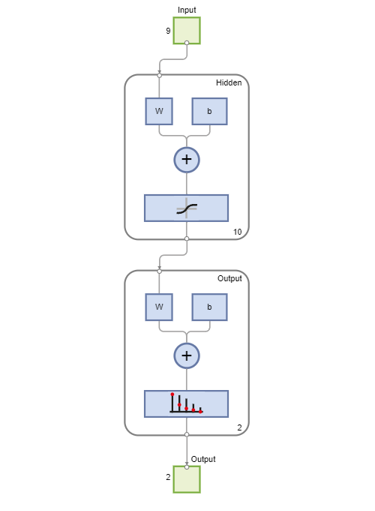


% 查看网络图。
view(net)

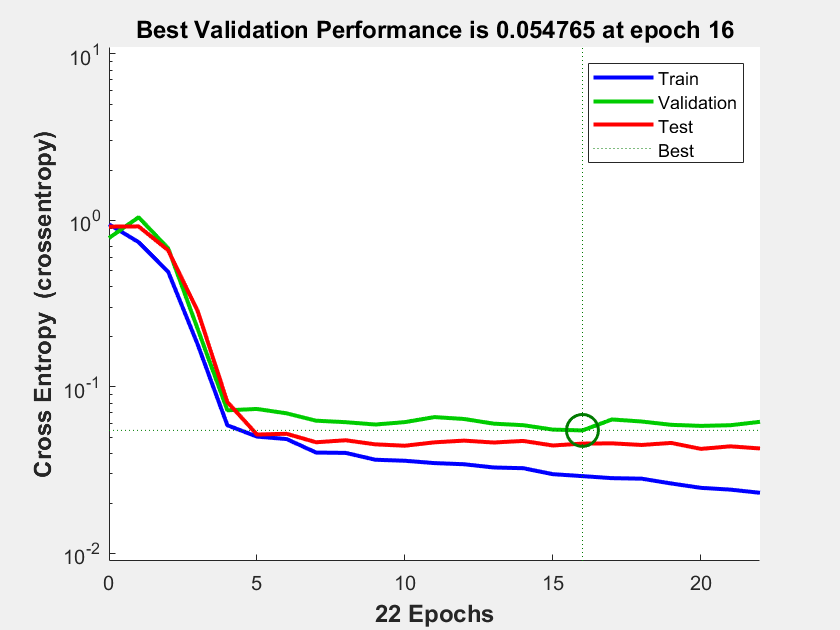

% 绘制训练、验证和测试性能图。
figure, plotperform(tr)

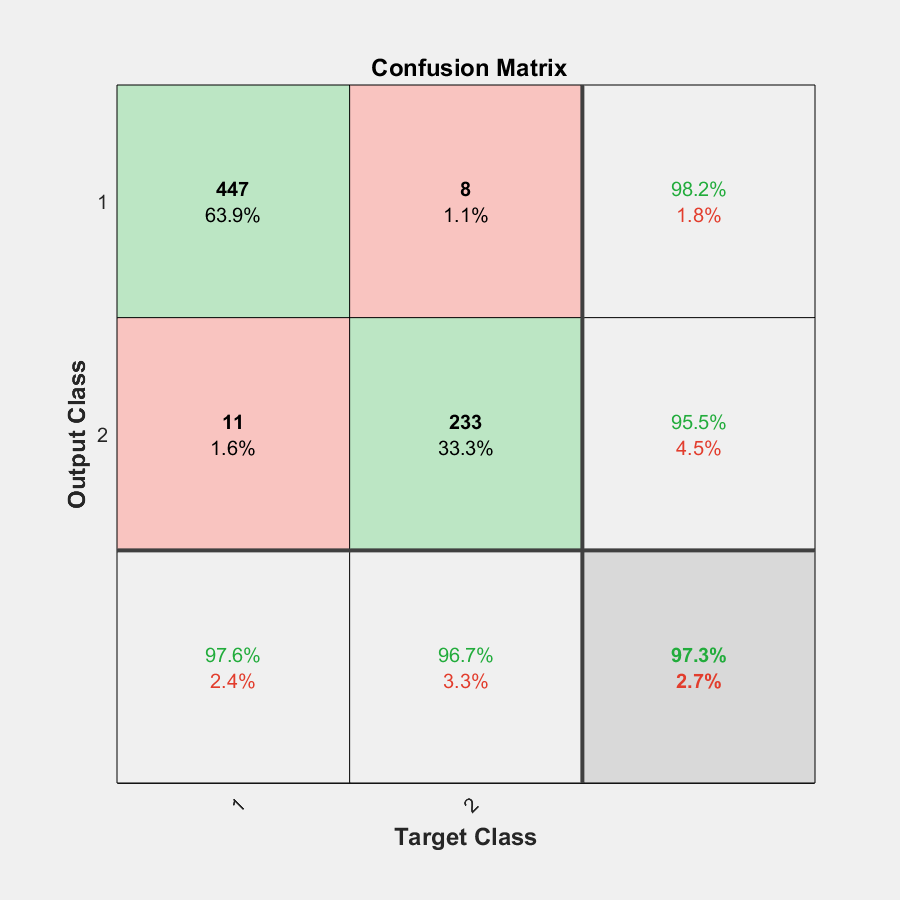

% 使用 plotconfusion 函数绘制混淆矩阵。它显示最终经过训练的网络发生的各种类型的误差。
figure, plotconfusion(targets,outputs)


% 对角线单元格显示正确分类的案例数，非对角线单元格显示误分类的案例数。
% 右下角的蓝色单元格显示正确分类的案例的总百分比（绿色）和误分类的案例的总百分比（红色）。
% 结果表明识别效果非常好。如果您需要更准确的结果，可以尝试下列方法之一：
% 使用 init 将初始网络权重和偏差重置为新值，然后再次训练。
% 增加隐藏神经元的数量。
% 增加训练向量的数量。
% 增加输入值的数量（如果有更多相关信息可用）。
% 尝试其他训练算法（请参阅训练算法）。
% 在此例中，网络响应是令人满意的，现在您可以将该网络用于新输入。
% 要进一步熟悉命令行操作，可以尝试下列任务：
% 在训练期间，打开绘图窗口（如混淆矩阵图），并观察其动画效果。
% 从命令行使用 plotroc 和 plottrainstate 等函数绘图。
% 此外，从命令行进行训练时，可以查看高级脚本以了解更多选项。
% 每次训练神经网络时，由于初始权重和偏置值不同，并且将数据划分为训练集、
% 验证集和测试集的方式也不同，可能会产生不同的解。
% 因此，针对同一问题训练的不同神经网络对同一输入可能给出不同输出。
% 为确保找到准确度良好的神经网络，需要多次重新训练。
% 如果需要更高的准确度，可以采用几种其他方法来改进初始解。
% 有关详细信息，请参阅提高浅层神经网络泛化能力，避免过拟合。